mem = imread('photo1.jpg');
black = uint8(zeros(size(mem(:,:,1))));

red = cat(3, mem(:,:,1), black, black);
gr = cat(3, black, mem(:,:,2), black);
bl = cat(3, black, black, mem(:,:,3));
norm = mem

norm = 309×250×3 uint8 array
norm(:,:,1) =

   245   246   248   248   250   248   249   250   250   250   248   248   250   250   251   248   252   249   251   255   255   255   250   243   236   238   244   247   246   247   251   255   250   249   248   250   254   254   253   251   251   247   242   232   227   228   234   239   240   241   242   245   250   253   255   255   255   255   254   254   251   250   251   248   245   245   249   254   255   255   255   252   250   245   239   236   237   237   235   232   223   217   214   211   208   204   200   196   191   188   186   183   181   181   180   183   189   194   194   195   194   192   192   191   190   187   188   186   183   180   175   171   164   158   152   147   144   144   145   145   146   146   145   145   144   143   143   141   143   157   176   194   205   217   229   237   246   247   249   250   249   248   247   243   241   239   238   235   233   231   231   231   230   230   231   230   232   231   231  

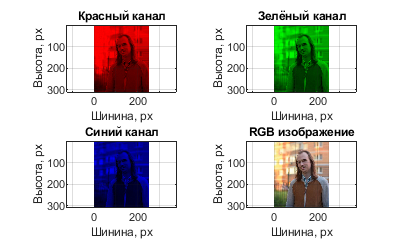

f2 = figure('Position', [50, 50, 1250, 750]);

subplot(2,2,1);
image(red)
grid on
axis('equal')
title('Красный канал')
xlabel('Шинина, px')
ylabel('Высота, px')

subplot(2,2,2)
image(gr)
grid on
axis('equal')
title('Зелёный канал')
xlabel('Шинина, px')
ylabel('Высота, px')



subplot(2,2,3)
image(bl)
grid on
axis('equal')
title('Синий канал')
xlabel('Шинина, px')
ylabel('Высота, px')



subplot(2,2,4)
image(norm)
grid on
axis('equal')
title('RGB изображение')
xlabel('Шинина, px')
ylabel('Высота, px')


saveas(f2, 'LABIC2.png')